right = imread('right.png');
left = imread('left.png');

dis = zeros(length(right), length(right(1)));
for r = 1:length(right) - 11
    for right_c = length(right(1)):-1:12
        r_patch = right(r:r+11, right_c-11:right_c)
        max_c = right_c;
        max_ncc = -1000000000;
        for left_c = right_c:-1:right_c-50;
            l_patch = left(r:r+11, left_c-11:left_c);
            temp = normxcorr2(r_patch, l_patch);
            if temp > max_ncc
                max_ncc = temp;
                max_c = left_c;
            end
        end
        dis(r, right_c) = 1 / (right_c - max_c);
    end
end


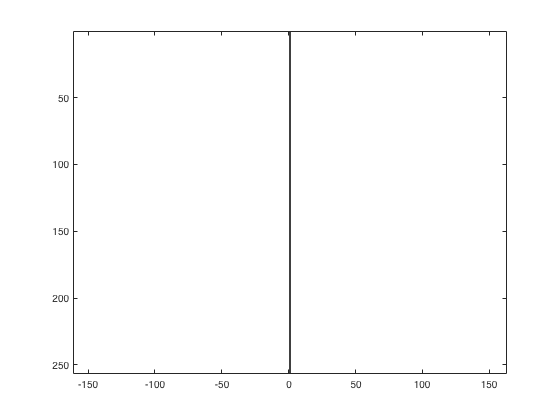

imagesc(dis, [0 50]); 
axis equal; 
colormap gray;